clear;
A = [0 1; 0 0];
B = [0; 1];
Bw = [1 0; 0 1];
%Bw = [1 0; 1 0];
%C2_1 = [1  0;    0 0];
%D2_1 = [0;     1];
x0 = [0; 0];
w0 = [0; 0];
C = [1 0];
Dw = [1 1];

Cz1 = [-1 2; 0 0];
Dz1 = [0; 1];


Cz2 = [0 0; -2 1];
Dz2 = [1; 0];

%=====Checkers=====
a1 = det(Dz1'*Dz1)

a1 = 1

ans_1 = Cz1'*Dz1

ans_1 =      0
     0


%U = [B A*B];
%du = rank(U)
V = [Cz1; Cz1*A];
dv = rank(V)

dv = 2

ans_2 = Cz2'*Dz2

ans_2 =      0
     0


a2 = det(Dz2'*Dz2)

a2 = 1


C_Z = Cz1;
D_Z = Dz1;

% Вычисляем необходимые компоненты
R = D_Z' * D_Z;
Q_riccati = C_Z' * C_Z;

% Решаем уравнение Риккати
[Q,~,K] = icare(A, B, Q_riccati, R, [], [], [], 1);

% Выводим решение
disp('Решение Q:');

Решение Q:


disp(Q);

    4.4495    1.0000
    1.0000    2.4495




K = -pinv(D_Z' * D_Z)*B'*Q;
disp('Решение K:');

Решение K:


disp(K);

   -1.0000   -2.4495



disp(eig(A+B*K));

   -0.5176
   -1.9319




%=====Передаточная функция====
syms s;

clear sys
W_wz = simplify((C_Z+D_Z*K)*inv(s*eye(2)-A-B*K)*Bw)

$$W\_wz = \begin{array}{l} \left(\begin{array}{cc} -\frac{s+\sqrt{6}+2}{\sigma_{2}} & \frac{2\,s-1}{\sigma_{2}}\\ -\frac{s\,\left(s^{2}-\sqrt{6}\,s+1\right)}{\sigma_{1}} & -\frac{\sqrt{6}\,s^{3}-5\,s^{2}+1}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=s^{4}-4\,s^{2}+1\\ \sigma_{2}=s^{2}+\sqrt{6}\,s+1 \end{array}$$


[out, in] = size(W_wz);
for i=1:out
    for j=1:in
        W_tmp = W_wz(i,j);
        [n, d] = numden(W_tmp);
        sys(i,j) = tf(sym2poly(n), sym2poly(d));
    end
end
sys

sys =
 
  From input 1 to output...
          -s - 4.449
   1:  -----------------
       s^2 + 2.449 s + 1
 
       -s^3 + 2.449 s^2 - s
   2:  --------------------
         s^4 - 4 s^2 + 1
 
  From input 2 to output...
            2 s - 1
   1:  -----------------
       s^2 + 2.449 s + 1
 
       -2.449 s^3 + 5 s^2 - 1
   2:  ----------------------
          s^4 - 4 s^2 + 1
 
Continuous-time transfer function.



%====AFC=====
simtime = 5;
w = [0:0.0001:simtime];
%plot_tf_matrix(sys, w);

n = norm(sys)

n = Inf

nn = norm(sys, Inf)

nn = 4.5660

sq = sqrt(trace(B'*Q*B))

sq = 1.5651

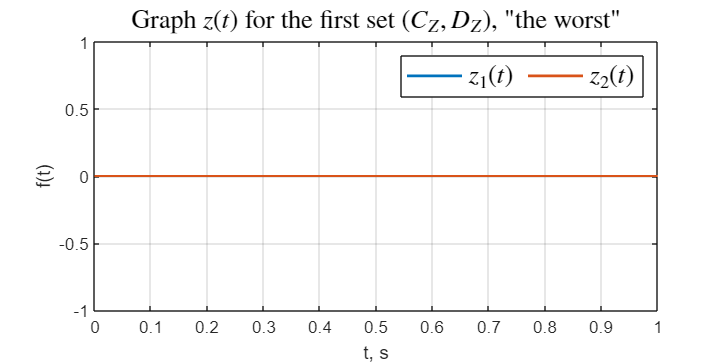


%plot_singular_valies(sys, w);

%=====Simulation=========

open_system('task_1_sim');
set_param('task_1_sim/z', 'VariableName', 'z')
out = sim('task_1_sim');

figure('Position', [100 100 800 400])
plot(out.x,'-', 'LineWidth',1.5);

grid()
title('Graph $z(t)$ for the first set $(C_Z, D_Z)$,  "the worst"','Interpreter','latex',  'FontSize', 14)
legend('$z_1(t)$', '$z_2(t)$', 'Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('f(t)')
xlabel('t, s')
hold off

function [] = plot_tf_matrix(sys, w)
    clf reset;
    hold all
    [out, in] = size(sys);
    %figure('Position', [100 100 800 400])
    for j=1:in
        for i=1:out    
            W = sys(i,j);
            [mag, ~] = bode(W, w);  % mag - амплитуда, второй аргумент (фаза) не используется
            h = squeeze(mag); 
            %h = freqs(cell2mat(W.Numerator), cell2mat(W.Denominator),w);
            mag = abs(h);
            
            loglog(w,mag,  'LineWidth', 1.5, 'DisplayName', "W_{w->z"+i+j+"}")
        end
    end
    
    title('Frequency response of $W_{w \to z}$ for the second set $(C_Z, D_Z)$','Interpreter','latex',  'FontSize', 14)
    xlabel('Frequency (rad/s)')
    ylabel('Magnitude(abs)')
    legend('$W_{w \to z}[1,1]$', '$W_{w \to z}[2,1]$', ...
        '$W_{w \to z}[1,2]$', '$W_{w \to z}[2,2]$', 'Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
    %legend
    grid on
    hold off
end

function [] = plot_singular_valies(sys, w)
    % Определяем частотное значение w
    if isempty(w)
         w = logspace(-2, 2, 1000);
    end
    
    % Вычисляем передаточную функцию для заданной частоты w
    [Gw,wout] = freqresp(sys, w);
    Gw = squeeze(Gw);
    sigmas = [];
    
    % Находим сингулярные числа матрицы Gw
    for i=1:length(Gw)
        sigmas(:, i) = svd(Gw(:,:,i));
    end
    
   
    plot(wout, sigmas,'LineWidth', 1.5);
     legend('$\sigma_1$', '$\sigma_2$', 'Interpreter','latex',  'FontSize', 14)
    %legend

    grid on;
    title('Singular numbers of $W_{w \to z}$ for the second set $(C_Z, D_Z)$','Interpreter','latex',  'FontSize', 14)
    ylabel("Singular numbers")
    xlabel('Frequency (rad/s)')
end